# Aplicación de las funciones

## Función `fnc_colebrook_white`

### Contexto

La **ecuación de Colebrook-White** es una fórmula empírica utilizada para calcular el **coeficiente de fricción **$f$ en el flujo turbulento de fluidos dentro de tuberías. Este coeficiente es esencial para estimar las pérdidas de energía o carga debido a la fricción en el flujo.


$$\frac{1}{\sqrt{f}} = -2\log{\left( \frac{\varepsilon/D}{3.7} + \frac{2.51}{Re\sqrt{f}}\right)}$$



$$Re = \frac{vD}{\nu}$$


Donde:

- $f \text{ (adimensional)}$ es el **coeficiente de fricción** de Darcy-Weisbach.

- $\varepsilon \text{ (mm)}$ es la **rugosidad absoluta** de la tubería (una medida de las irregularidades de la pared interna).

- $D \text{ (mm)}$ es el **diámetro interno** de la tubería.

- $Re \text{ (adimensional)}$ es el **número de Reynolds**, que determina el régimen del flujo (laminar, transitorio o turbulento).

- $v \text{ (m/s)}$ es la **velocidad promedio** del fluido en la tubería.

- $\nu \text{ (m}^2\text{/s)}$ es la **velocidad cinemática** del fluido en la tubería.

### Aplicación

help fnc_colebrook_white

 fnc_colebrook_white   Determinar el factor de fricción de Darcy utilizando la ecuación de Colebrook-White.
   f = fnc_colebrook_white(parametros, parametros, parametros, parametros)

    Entradas:
    
       Velocidad {escalar}: Velocidad del flujo [m/s]
       Diametro {escalar}: Diámetro de la tubería o diámetro hidráulico del
       canal [m]
       Rugosidad_absoluta {escalar}: Rugosidad absoluta del material [m]
       *Velocidad_cinematica {escalar=1.004e-6}: Velocidad cinemática del flujo
       [m^2/s]
    
    Salidas
    
       f {escalar}: Factor de fricción de Darcy
    
    Documentation for fnc_colebrook_white



% Entradas
v = 3;              % Velocidad [m/s]
D = 0.10;           % Diámetro [m]
k = 3e-3;           % Rugosidad absoluta [m]

% Procedimiento
f = fnc_colebrook_white("Velocidad", v, "Diametro", D, "Rugosidad_absoluta", k);
msg = "Velocidad: %.2f m/s\nDiámetro: %.2f m = %d mm\n" + ...
    "Rugosidad absoluta: %.4f m = %d mm\n\nFactor de fricción: %.4f\n";

% Resultado
fprintf(msg, v, D, D*1000, k, k*1000, f);

Velocidad: 3.00 m/s
Diámetro: 0.10 m = 100 mm
Rugosidad absoluta: 0.0030 m = 3 mm

Factor de fricción: 0.0573


## Función `fnc_darcy_weisbach`

### Contexto

La **ecuación de Darcy-Weisbach** es una fórmula fundamental en la mecánica de fluidos que se utiliza para calcular la **pérdida de energía** o **pérdida de carga** en el flujo de un fluido a través de una tubería debido a la fricción.


$$h_f = f \frac{L}{D}\frac{v^2}{2g}$$


Despejando la velocidad, $v$, en la ecuación anterior se obtiene:


$$v = \sqrt{\frac{2gD}{f}\frac{h_f}{L}} = \sqrt{\frac{2gDS}{f}}$$


Donde:

- $h_f \text{ (m)}$ es la **pérdida de carga** o pérdida de energía por fricción.

- $f \text{ (adimensional)}$ es el **coeficiente de fricción** de Darcy-Weisbach.

- $L \text{ (m)}$ es la **longitud** de la tubería.

- $D \text{ (m)}$ es el **diámetro interno** de la tubería.

- $v \text{ (m/s)}$ es la **velocidad promedio** del fluido en la tubería.

- $g \text{ (m/s}^2\text{)}$ es la **aceleración debida a la gravedad**.

- $S = \frac{h_f}{L} \text{ (m/m)}$ es la **pendiente longitudinal** de la tubería.

### Aplicación

help fnc_darcy_weisbach

 fnc_darcy_weisbach   Determinar la velocidad mediante la ecuación de Darcy-Weisbach.
   varargout = fnc_darcy_weisbach(entradas, entradas, entradas, entradas, entradas)

    Opcionalmente se obtiene el fractor de fricción f de Darcy, mediante la
    ecuación de Colebrook-White, y el número de Reynolds.
    
    Entradas:
    
       Diametro {escalar}: Diámetro de la tubería [m]
       Pendiente {escalar}: Pendiente longitudinal de la tubería [m/m]
       Rugosidad_absoluta {escalar}: Rugosidad absoluta del material de la
       tubería [m]
       *Velocidad_cinematica {escalar=1.004e-6}: Velocidad cinemática del flujo
       en la tubería [m^2/s]
       *Gravedad {escalar=9.81}: Gravedad [m/s^2]
    
    Salidas:
    
       Velocidad {escalar}: Velocidad del flujo en la tubería [m/s]
       *Factor_friccion {escalar}: Factor de fricción f de Darcy
       *Reynolds {escalar}: Número de Reynolds del flujo en la tubería
    
    

% Entradas
D = 0.10;           % Diámetro [m]
S = 0.05;           % Pendiente [m/m]
k = 3e-3;           % Rugosidad absoluta [m]

% Procedimiento
[v, f, Re] = fnc_darcy_weisbach("Diametro", D, "Pendiente", S, "Rugosidad_absoluta", k);
msg = "Diámetro: %.2f m = %d mm\nPendiente: %.2f m/m = %.2f %%\n" + ...
    "Rugosidad absoluta: %.4f m = %d mm\n\nVelocidad: %.2f m/s\n" + ...
    "Factor de fricción: %.4f\nNúmero de Reynolds: %d\n";

% Resultado
fprintf(msg, D, D*1000, S, S*100, k, k*1000, v, f, Re);

Diámetro: 0.10 m = 100 mm
Pendiente: 0.05 m/m = 5.00 %
Rugosidad absoluta: 0.0030 m = 3 mm

Velocidad: 1.31 m/s
Factor de fricción: 0.0574
Número de Reynolds: 1.301997e+05


## Función `fnc_diagrama_moody`

### Contexto

El **diagrama de Moody** es una herramienta gráfica que se usa para determinar el **coeficiente de fricción** en el flujo de fluidos a través de tuberías. Este coeficiente de fricción es clave en el cálculo de la pérdida de energía debida a la fricción en el flujo de un fluido.

El diagrama se basa en la **ecuación de Colebrook-White** que relaciona el coeficiente de fricción $f$, el número de Reynolds $Re$, y la rugosidad relativa $\frac{\varepsilon}{D}$:


$$\frac{1}{\sqrt{f}} = -2\log{\left( \frac{\varepsilon/D}{3.7} + \frac{2.51}{Re\sqrt{f}}\right)}$$


El diagrama facilita la interpretación del comportamiento del flujo laminar, transitorio y turbulento para distintos valores de Reynolds y rugosidad.

El diagrama de Moody esperado es similar al siguiente:

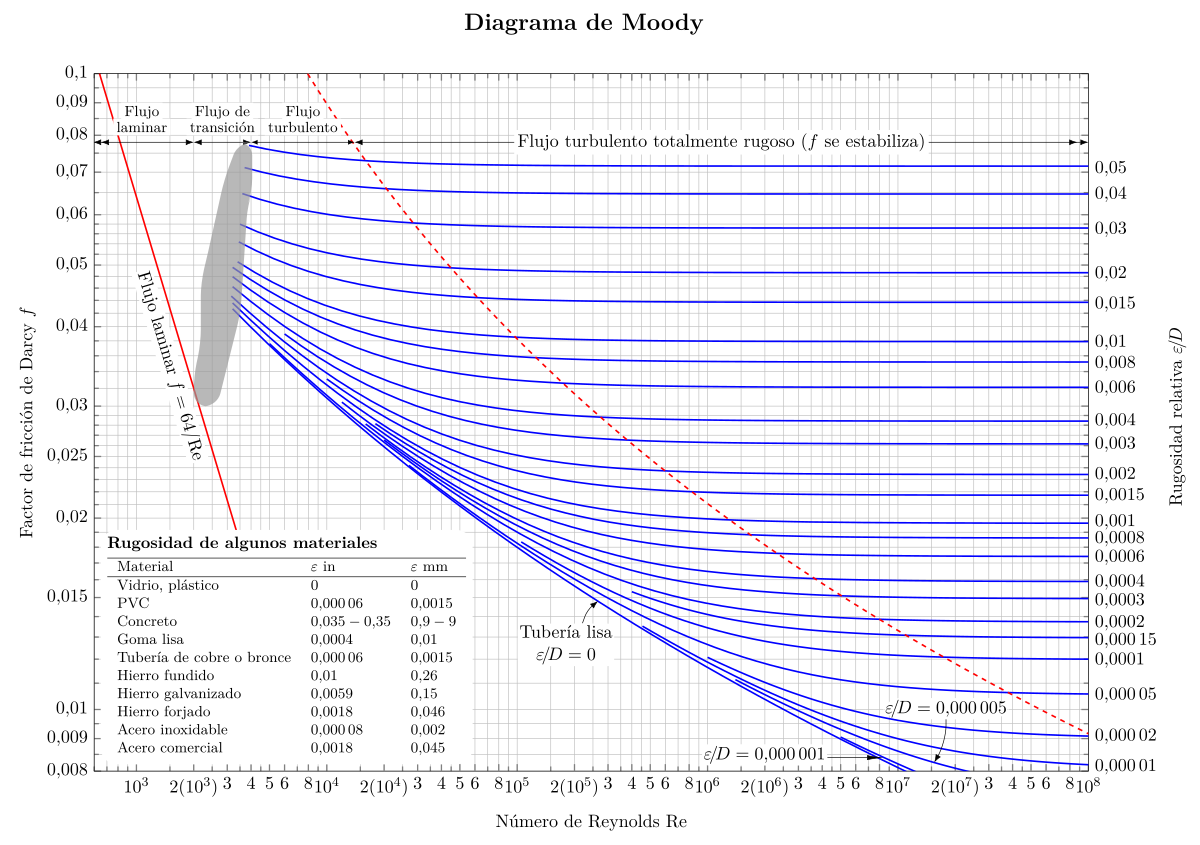

No obstante, **sólo se recomienda el uso de la función para fines académicos, no para fines prácticos.** Debido al gran avance de la tecnología y muchas herramientas asociadas, especialmente la programación, es obsoleto el uso del diagrama fuera del ámbito académico. Si se desea determinar el coeficiente de fricción $f$, es mejor utilizar alguna de las otras funciones detalladas en este documento.

### Aplicación

help fnc_diagrama_moody

 fnc_diagrama_moody   Generar el diagrama de Moody.
   fnc_diagrama_moody(parametros)

    Entradas:
    
       Rugosidad_relativa {escalar | vector}: Rugosidad relativa del fluido.
    
    Salidas:
    
       Gráfica del diagrama de Moody.
    
    Documentation for fnc_diagrama_moody



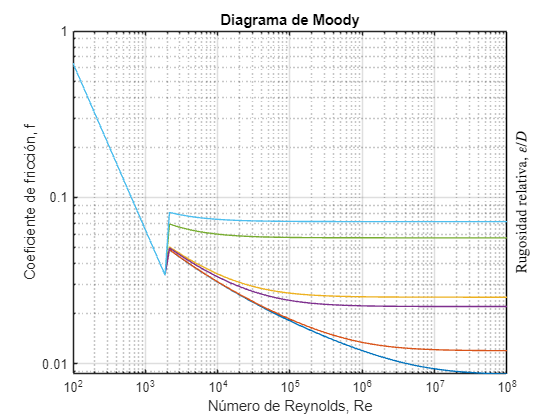

% Entradas
D = 100;                            % Diamétro [mm]
k = [0.0015 0.01 0.26 0.16 3 5];    % Rugosidad absoluta [mm]

% Procedimiento y resultado
kD = k / D;
fnc_diagrama_moody("Rugosidad_relativa", kD)